# **COMPARAISON ASYMPTOMATIQUE-POSTOPERATOIRE (Indépendants)**

% ANALYSE COMPARATIVE DES SYNERGIES MUSCULAIRES 
% Chargement des données
W_post = Profilglobalsynergiespost; % Groupe post-opératoire (9 sujets)
W_asymp = Profilglobalsynergies;    % Groupe asymptomatique (20 sujets)

noms_muscles = {'Ant. deltoid', 'Mid. deltoid', 'Post. deltoid', ...
                'Mid. trapezius', 'Up. trapezius', 'Ant. serratus'};

% Nombre de sujets dans chaque groupe
n_post = 9;
n_asymp = 20;

% ---- EXTRACTION DES SYNERGIES ----
synergy1_post = zeros(6, n_post);
synergy2_post = zeros(6, n_post);
for i = 1:n_post
    synergy1_post(:, i) = W_post(:, (i-1)*2 + 1);
    synergy2_post(:, i) = W_post(:, (i-1)*2 + 2);
end

synergy1_asymp = zeros(6, n_asymp);
synergy2_asymp = zeros(6, n_asymp);
for i = 1:n_asymp
    synergy1_asymp(:, i) = W_asymp(:, (i-1)*2 + 1);
    synergy2_asymp(:, i) = W_asymp(:, (i-1)*2 + 2);
end

% ---- STATISTIQUES DESCRIPTIVES ----
t_val_post = tinv(0.975, n_post-1);
t_val_asymp = tinv(0.975, n_asymp-1);

mean_synergy1_post = mean(synergy1_post, 2);
std_synergy1_post = std(synergy1_post, 0, 2);
sem_synergy1_post = std_synergy1_post / sqrt(n_post);
IC_synergy1_post = t_val_post * sem_synergy1_post;

mean_synergy2_post = mean(synergy2_post, 2);
std_synergy2_post = std(synergy2_post, 0, 2);
sem_synergy2_post = std_synergy2_post / sqrt(n_post);
IC_synergy2_post = t_val_post * sem_synergy2_post;

mean_synergy1_asymp = mean(synergy1_asymp, 2);
std_synergy1_asymp = std(synergy1_asymp, 0, 2);
sem_synergy1_asymp = std_synergy1_asymp / sqrt(n_asymp);
IC_synergy1_asymp = t_val_asymp * sem_synergy1_asymp;

mean_synergy2_asymp = mean(synergy2_asymp, 2);
std_synergy2_asymp = std(synergy2_asymp, 0, 2);
sem_synergy2_asymp = std_synergy2_asymp / sqrt(n_asymp);
IC_synergy2_asymp = t_val_asymp * sem_synergy2_asymp;

% ---- TESTS STATISTIQUES AVEC VÉRIFICATION DES CONDITIONS ----
p_values_synergy1 = zeros(6, 1);
p_values_synergy2 = zeros(6, 1);
test_used_synergy1 = strings(6, 1);
test_used_synergy2 = strings(6, 1);

for muscle = 1:6
    data_post = synergy1_post(muscle, :)';
    data_asymp = synergy1_asymp(muscle, :)';

    p_sw_post = swtest(data_post, 0.05);
    p_sw_asymp = swtest(data_asymp, 0.05);

    normal_post = all(~isnan(data_post)) && (length(data_post) > 3) && (p_sw_post > 0.05);
    normal_asymp = all(~isnan(data_asymp)) && (length(data_asymp) > 3) && (p_sw_asymp > 0.05);

    fprintf('\n--- Muscle %s (Synergie 1) ---\n', noms_muscles{muscle});
    fprintf('Normalité Post-op : p = %.3f (%s)\n', p_sw_post, ternary(p_sw_post < 0.05, 'non normal', 'normal'));
    fprintf('Normalité Asymp   : p = %.3f (%s)\n', p_sw_asymp, ternary(p_sw_asymp < 0.05, 'non normal', 'normal'));

    if normal_post && normal_asymp
        [~, p_var] = vartest2(data_post, data_asymp);
        fprintf('Homogénéité des variances : p = %.3f (%s)\n', p_var, ternary(p_var < 0.05, 'variances inégales', 'variances égales'));
        if p_var >= 0.05
            [~, p_values_synergy1(muscle)] = ttest2(data_post, data_asymp);
            test_used_synergy1(muscle) = "t-test";
        else
            [~, p_values_synergy1(muscle)] = ttest2(data_post, data_asymp, 'Vartype', 'unequal');
            test_used_synergy1(muscle) = "Welch";
        end
    else
        p_values_synergy1(muscle) = ranksum(data_post, data_asymp);
        test_used_synergy1(muscle) = "Mann-Whitney";
    end
    fprintf('→ Test utilisé : %s\n', test_used_synergy1(muscle));

    data_post = synergy2_post(muscle, :)';
    data_asymp = synergy2_asymp(muscle, :)';

    p_sw_post = swtest(data_post, 0.05);
    p_sw_asymp = swtest(data_asymp, 0.05);

    normal_post = all(~isnan(data_post)) && (length(data_post) > 3) && (p_sw_post > 0.05);
    normal_asymp = all(~isnan(data_asymp)) && (length(data_asymp) > 3) && (p_sw_asymp > 0.05);

    fprintf('\n--- Muscle %s (Synergie 2) ---\n', noms_muscles{muscle});
    fprintf('Normalité Post-op : p = %.3f (%s)\n', p_sw_post, ternary(p_sw_post < 0.05, 'non normal', 'normal'));
    fprintf('Normalité Asymp   : p = %.3f (%s)\n', p_sw_asymp, ternary(p_sw_asymp < 0.05, 'non normal', 'normal'));

    if normal_post && normal_asymp
        [~, p_var] = vartest2(data_post, data_asymp);
        fprintf('Homogénéité des variances : p = %.3f (%s)\n', p_var, ternary(p_var < 0.05, 'variances inégales', 'variances égales'));
        if p_var >= 0.05
            [~, p_values_synergy2(muscle)] = ttest2(data_post, data_asymp);
            test_used_synergy2(muscle) = "t-test";
        else
            [~, p_values_synergy2(muscle)] = ttest2(data_post, data_asymp, 'Vartype', 'unequal');
            test_used_synergy2(muscle) = "Welch";
        end
    else
        p_values_synergy2(muscle) = ranksum(data_post, data_asymp);
        test_used_synergy2(muscle) = "Mann-Whitney";
    end
    fprintf('→ Test utilisé : %s\n', test_used_synergy2(muscle));
end


--- Muscle Ant. deltoid (Synergie 1) ---


Normalité Post-op : p = 1.000 (normal)


Normalité Asymp   : p = 0.000 (non normal)


→ Test utilisé : Mann-Whitney



--- Muscle Ant. deltoid (Synergie 2) ---


Normalité Post-op : p = 1.000 (normal)


Normalité Asymp   : p = 1.000 (normal)


Homogénéité des variances : p = 0.000 (variances inégales)


→ Test utilisé : Welch



--- Muscle Mid. deltoid (Synergie 1) ---


Normalité Post-op : p = 0.000 (non normal)


Normalité Asymp   : p = 0.000 (non normal)


→ Test utilisé : Mann-Whitney



--- Muscle Mid. deltoid (Synergie 2) ---


Normalité Post-op : p = 0.000 (non normal)


Normalité Asymp   : p = 0.000 (non normal)


→ Test utilisé : Mann-Whitney



--- Muscle Post. deltoid (Synergie 1) ---


Normalité Post-op : p = 0.000 (non normal)


Normalité Asymp   : p = 1.000 (normal)


→ Test utilisé : Mann-Whitney



--- Muscle Post. deltoid (Synergie 2) ---


Normalité Post-op : p = 1.000 (normal)


Normalité Asymp   : p = 1.000 (normal)


Homogénéité des variances : p = 0.021 (variances inégales)


→ Test utilisé : Welch



--- Muscle Mid. trapezius (Synergie 1) ---


Normalité Post-op : p = 1.000 (normal)


Normalité Asymp   : p = 0.000 (non normal)


→ Test utilisé : Mann-Whitney



--- Muscle Mid. trapezius (Synergie 2) ---


Normalité Post-op : p = 1.000 (normal)


Normalité Asymp   : p = 0.000 (non normal)


→ Test utilisé : Mann-Whitney



--- Muscle Up. trapezius (Synergie 1) ---


Normalité Post-op : p = 0.000 (non normal)


Normalité Asymp   : p = 0.000 (non normal)


→ Test utilisé : Mann-Whitney



--- Muscle Up. trapezius (Synergie 2) ---


Normalité Post-op : p = 0.000 (non normal)


Normalité Asymp   : p = 1.000 (normal)


→ Test utilisé : Mann-Whitney



--- Muscle Ant. serratus (Synergie 1) ---


Normalité Post-op : p = 0.000 (non normal)


Normalité Asymp   : p = 0.000 (non normal)


→ Test utilisé : Mann-Whitney



--- Muscle Ant. serratus (Synergie 2) ---


Normalité Post-op : p = 0.000 (non normal)


Normalité Asymp   : p = 1.000 (normal)


→ Test utilisé : Mann-Whitney



n_param_sy1 = sum(test_used_synergy1 == "t-test" | test_used_synergy1 == "Welch");
n_nonparam_sy1 = sum(test_used_synergy1 == "Mann-Whitney");
n_param_sy2 = sum(test_used_synergy2 == "t-test" | test_used_synergy2 == "Welch");
n_nonparam_sy2 = sum(test_used_synergy2 == "Mann-Whitney");

fprintf('\n=== Vérification des conditions statistiques ===\n');


=== Vérification des conditions statistiques ===


fprintf('Les hypothèses de normalité ont été testées via le test de Shapiro-Wilk (swtest).\n');

Les hypothèses de normalité ont été testées via le test de Shapiro-Wilk (swtest).


fprintf('Lorsque la normalité ou l’homogénéité des variances n’étaient pas vérifiées, des tests alternatifs (Welch ou Mann-Whitney) ont été utilisés.\n');

Lorsque la normalité ou l’homogénéité des variances n’étaient pas vérifiées, des tests alternatifs (Welch ou Mann-Whitney) ont été utilisés.


fprintf('Les types de tests appliqués sont résumés pour chaque muscle et chaque synergie.\n');

Les types de tests appliqués sont résumés pour chaque muscle et chaque synergie.



fprintf('\nRésumé :\n');


Résumé :


fprintf('Synergie 1 : %d tests paramétriques, %d non paramétriques\n', n_param_sy1, n_nonparam_sy1);

Synergie 1 : 0 tests paramétriques, 6 non paramétriques


fprintf('Synergie 2 : %d tests paramétriques, %d non paramétriques\n', n_param_sy2, n_nonparam_sy2);

Synergie 2 : 2 tests paramétriques, 4 non paramétriques


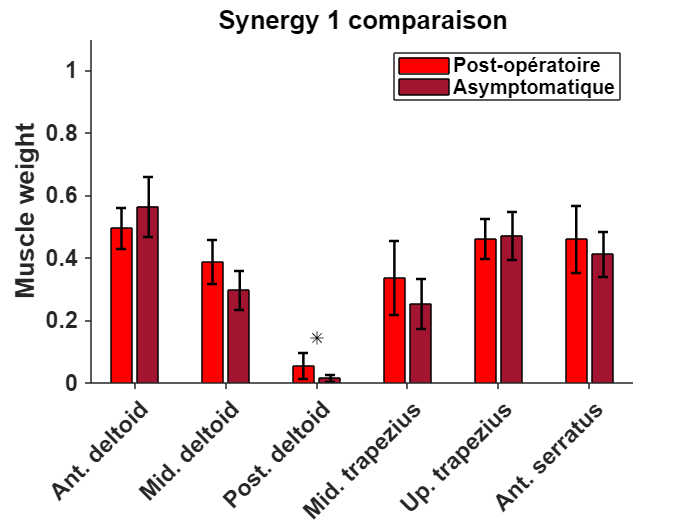


% ---- VISUALISATIONS ----
% 1. Comparaison des synergies 1 entre groupes
figure;
x = 1:6;
% Correction ici: créer une matrice avec les deux vecteurs comme colonnes
data_to_plot = [mean_synergy1_post, mean_synergy1_asymp];
b = bar(x, data_to_plot);
b(1).FaceColor = 'r';
b(2).FaceColor = [0.6350 0.0780 0.1840];
hold on

% Ajout des barres d'erreur (IC 95%)
% Positions ajustées pour les barres d'erreur
x1 = x - 0.15;
x2 = x + 0.15;
errorbar(x1, mean_synergy1_post, IC_synergy1_post, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);
errorbar(x2, mean_synergy1_asymp, IC_synergy1_asymp, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);

% Signification statistique
for i = 1:6
    if p_values_synergy1(i) < 0.05
        plot(i, max([mean_synergy1_post(i)+IC_synergy1_post(i), mean_synergy1_asymp(i)+IC_synergy1_asymp(i)])+0.05, '*k', 'MarkerSize', 8);
    end
end

title('Synergy 1 comparaison', 'FontSize', 18, 'FontWeight', 'bold');
ylabel('Muscle weight', 'FontSize', 14);
xticks(1:6);
xticklabels(noms_muscles);
xtickangle(45);
ylim([0 1.1]);
set(gca, 'FontSize', 14, 'FontWeight', 'bold', 'TickDir', 'out', 'Box', 'off');
legend({'Post-opératoire', 'Asymptomatique'}, 'Location', 'northeast', 'FontSize', 12);
hold off;

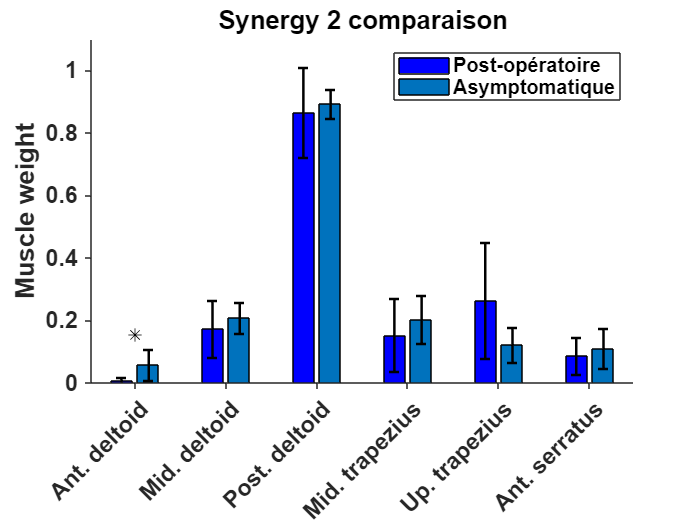


% 2. Comparaison des synergies 2 entre groupes
figure;
% Correction similaire pour la deuxième synergie
data_to_plot2 = [mean_synergy2_post, mean_synergy2_asymp];
b = bar(x, data_to_plot2);
b(1).FaceColor = 'b';
b(2).FaceColor = [0 0.4470 0.7410];
hold on

% Ajout des barres d'erreur (IC 95%)
errorbar(x1, mean_synergy2_post, IC_synergy2_post, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);
errorbar(x2, mean_synergy2_asymp, IC_synergy2_asymp, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);

% Signification statistique
for i = 1:6
    if p_values_synergy2(i) < 0.05
        plot(i, max([mean_synergy2_post(i)+IC_synergy2_post(i), mean_synergy2_asymp(i)+IC_synergy2_asymp(i)])+0.05, '*k', 'MarkerSize', 8);
    end
end

title('Synergy 2 comparaison', 'FontSize', 18, 'FontWeight', 'bold');
ylabel('Muscle weight', 'FontSize', 14);
xticks(1:6);
xticklabels(noms_muscles);
xtickangle(45);
ylim([0 1.1]);
set(gca, 'FontSize', 14, 'FontWeight', 'bold', 'TickDir', 'out', 'Box', 'off');
legend({'Post-opératoire', 'Asymptomatique'}, 'Location', 'northeast', 'FontSize', 12);
hold off;


% Comptage des types de tests utilisés
n_param_sy1 = sum(test_used_synergy1 == "t-test" | test_used_synergy1 == "Welch");
n_nonparam_sy1 = sum(test_used_synergy1 == "Mann-Whitney");

n_param_sy2 = sum(test_used_synergy2 == "t-test" | test_used_synergy2 == "Welch");
n_nonparam_sy2 = sum(test_used_synergy2 == "Mann-Whitney");

%% 4. Tableau récapitulatif des p-values
% Ajouter des astérisques pour les p-values < 0.05
highlight = @(p) sprintf('%.3f%s', p, ternary(p < 0.05, ' *', ''));

% Appliquer la fonction à chaque valeur
synergy1_str = arrayfun(@(p) highlight(p), p_values_synergy1, 'UniformOutput', false);
synergy2_str = arrayfun(@(p) highlight(p), p_values_synergy2, 'UniformOutput', false);

% Créer une table de chaînes
T_str = table(synergy1_str(:), synergy2_str(:), ...
              'VariableNames', {'Synergie_1', 'Synergie_2'}, ...
              'RowNames', noms_muscles);

% Affichage
disp('=== Tableau des p-values par muscle ( * : p < 0.05 ) ===');

=== Tableau des p-values par muscle ( * : p < 0.05 ) ===


disp(T_str);

                      Synergie_1     Synergie_2 
                      ___________    ___________

    Ant. deltoid      {'0.094'  }    {'0.044 *'}
    Mid. deltoid      {'0.104'  }    {'0.494'  }
    Post. deltoid     {'0.047 *'}    {'0.688'  }
    Mid. trapezius    {'0.268'  }    {'0.409'  }
    Up. trapezius     {'0.724'  }    {'0.063'  }
    Ant. serratus     {'0.494'  }    {'1.000'  }




%% 5. Corrélation entre les profils
% Calculer les corrélations entre les profils des deux groupes
corr_synergy1 = corrcoef(mean_synergy1_post, mean_synergy1_asymp);
corr_synergy2 = corrcoef(mean_synergy2_post, mean_synergy2_asymp);

% Afficher les résultats avec interprétation
fprintf('\n=== Corrélation entre les profils de synergies ===\n');


=== Corrélation entre les profils de synergies ===


fprintf('Synergie 1 : r = %.3f\n', corr_synergy1(1,2));

Synergie 1 : r = 0.957


if corr_synergy1(1,2) > 0.7
    fprintf('→ Forte similarité entre les profils de la Synergie 1 (asymptomatiques vs post-opératoires).\n');
elseif corr_synergy1(1,2) > 0.4
    fprintf('→ Similarité modérée entre les profils de la Synergie 1.\n');
else
    fprintf('→ Faible similarité entre les profils de la Synergie 1.\n');
end

→ Forte similarité entre les profils de la Synergie 1 (asymptomatiques vs post-opératoires).



fprintf('Synergie 2 : r = %.3f\n', corr_synergy2(1,2));

Synergie 2 : r = 0.972


if corr_synergy2(1,2) > 0.7
    fprintf('→ Forte similarité entre les profils de la Synergie 2 (asymptomatiques vs post-opératoires).\n');
elseif corr_synergy2(1,2) > 0.4
    fprintf('→ Similarité modérée entre les profils de la Synergie 2.\n');
else
    fprintf('→ Faible similarité entre les profils de la Synergie 2.\n');
end

→ Forte similarité entre les profils de la Synergie 2 (asymptomatiques vs post-opératoires).
